# Problem Set 4

### Karthik Desingu

***Reference: ****Tyson, J., Chen, K., Novak, B.* (2003). **Sniffers, buzzers, toggles and blinkers: dynamics of regulatory and signaling pathways in the cell.** Current opinion in cell biology 15(2), 221 - 231. 

We are going to choose oscillator 2c from Figure 2: the substrate depletion oscillator

This model is can be expressed as :

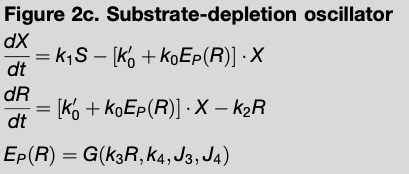

where :

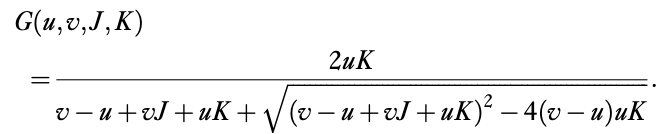

**Question 1****. **

%%%%%%%%% parameter structure for ODE
p.k0p = 0.01; 				%s^(-1)
p.k0 = 0.4;				    %s^(-1) uM^(-1)
p.k1 = 1; 				    %s^(-1)
p.k2 = 1; 				    %s^(-1)
p.k3 = 1;
p.k4 = 0.3;			        
p.J3 = 0.05; 				%dimensionless
p.J4 = 0.05; 				%dimensionless
%choose a signal value in the middle of the oscillating range in Figure 2c
%note that the units are uM^(-1)

*(i) Choose a signal concentration p.Signal in the middle of the oscillation range in Figure 2c (right), solve with ODE45, and plot  for 0 to 200 s.*

p.Signal = 0.25;		           %Signal uM^(-1) in middle of the oscillating region 

%%%%%%%%% goldbeter-koshland function
GK = @(V1,V2,K1,K2) 2.*V1.*K2 ./ (V2-V1+V2.*K1+V1.*K2 + ...
    sqrt((V2-V1+V2.*K1+V1.*K2).^2 - 4.*(V2-V1).*V1.*K2));

%%%%%%%%%%%%%%%%%%%%%%% Initial condition
X0=[...
    0;                      %X
    0];                     %R


Write down the ODE

%%%%%%%%%%%%%%%%%%%%%%% ODE
dXdt = @(X,p)[(p.k1 .* p.Signal) - (p.k0p + (p.k0 .* GK(p.k3 .* X(2), p.k4, p.J3, p.J4))).*X(1); ...
    (p.k0p + (p.k0 .* GK(p.k3.*X(2), p.k4, p.J3, p.J4))).*X(1) - (p.k2 .* X(2))];
%%%% start and end times (use these, though you might change them)
tspan=[0,200];
%%%%%%%% calculkate X(t) and R(t) for the signal in the middle of the range
[t_mid,X_mid] = ode45(@(t,X) dXdt(X,p), tspan, X0);

Plot X and R

figure;

plot X code here

plot(X_mid(:, 1), t_mid, 'g-');
hold on;

plot R here

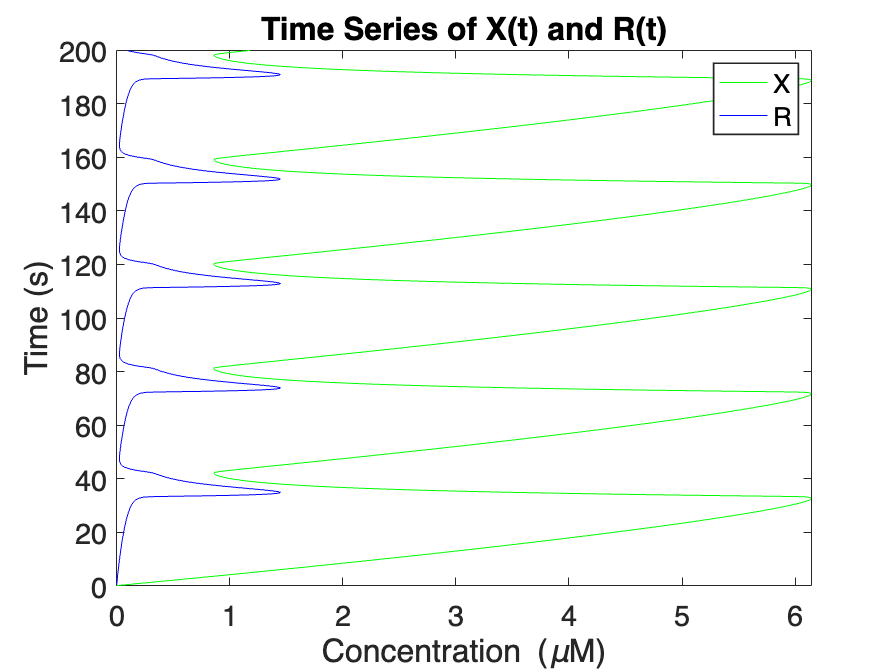

plot(X_mid(:, 2), t_mid, 'b-');
title ('Time Series of X(t) and R(t)')
xlabel('Concentration (\muM)')
ylabel('Time (s)')
box on;
legend('X', 'R')
drawnow;
set(gca,'FontName','Helvetica','FontSize',18,'GridAlpha',0.15,'color','w','LineWidth',1);

*(ii) Choose two other values of *$S$* : one outside the range on the low side and one on the high side. Solve the equations and plot *$R(t)$

**Low Signal**

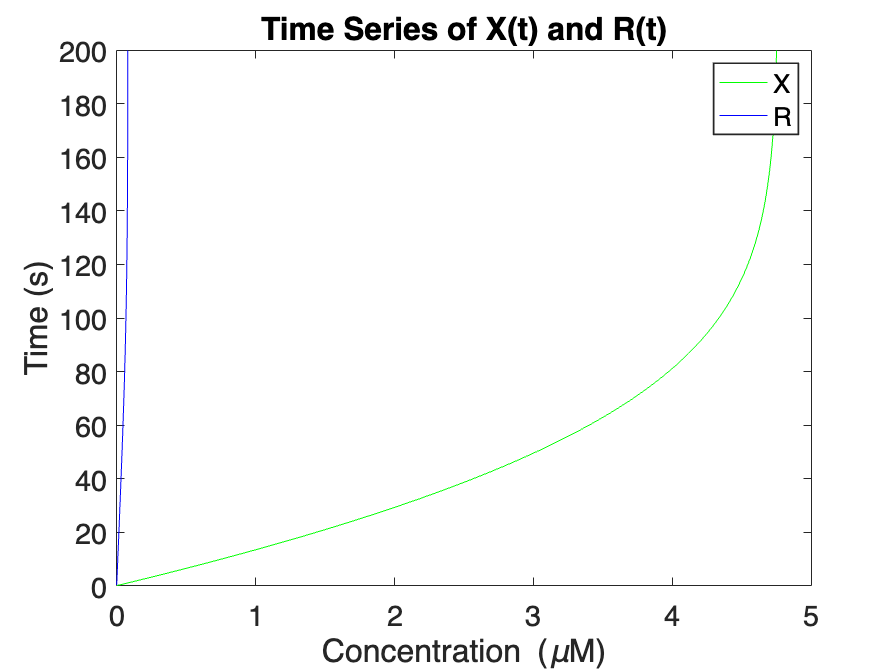

p.Signal = 0.08;
[t_low, X_low] = ode45(@(t, X) dXdt(X, p), tspan, X0);

% plot.
figure;
plot(X_low(:, 1), t_low, 'g-');
hold on;
plot(X_low(:, 2), t_low, 'b-');
title ('Time Series of X(t) and R(t)')
xlabel('Concentration (\muM)')
ylabel('Time (s)')
box on;
legend('X', 'R')
drawnow;
set(gca,'FontName','Helvetica','FontSize',18,'GridAlpha',0.15,'color','w','LineWidth',1);

**High Signal**

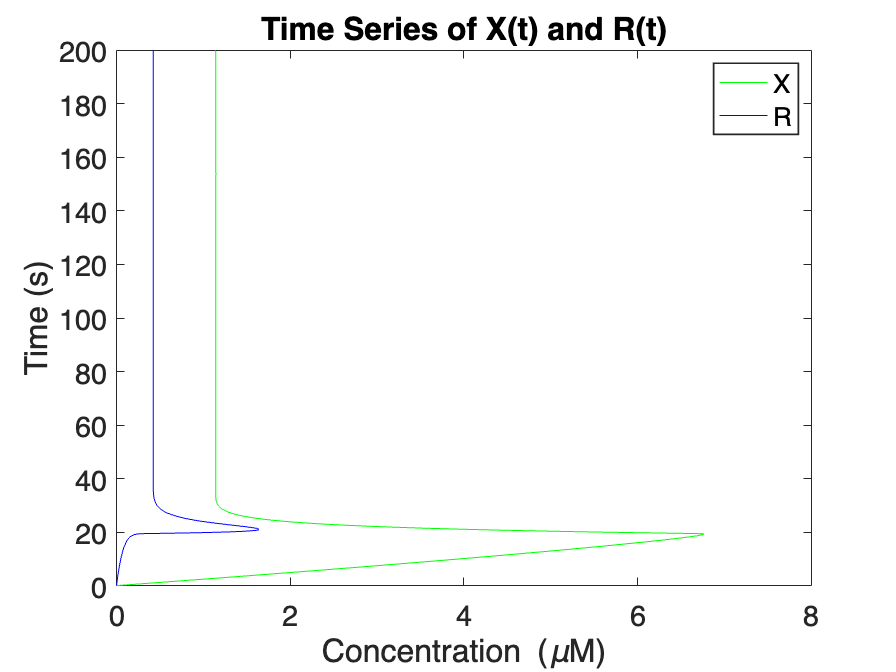

%%%% high signal
p.Signal = 0.42;           
[t_high, X_high] = ode45(@(t, X) dXdt(X, p), tspan, X0);

% plot.
figure;
plot(X_high(:, 1), t_high, 'g-');
hold on;
plot(X_high(:, 2), t_high, 'b-');
title ('Time Series of X(t) and R(t)')
xlabel('Concentration (\muM)')
ylabel('Time (s)')
box on;
legend('X', 'R')
drawnow;
set(gca,'FontName','Helvetica','FontSize',18,'GridAlpha',0.15,'color','w','LineWidth',1);

*(iii) In a sentence or two summarize your findings.*

For the signal value chosen in the middle of the oscillation range, as one would expect, the concentrations of X and R rise and fall in synchrony; this causes the system to oscillate. X keeps rising initially; once it becomes very high, it causes R to rise; but when both X and R high, X levels fall, eventually causing R to fall as well. Then the cycle restarts.

On the contrary, the concentrations of X and R stabilize to specific values after an initial interval of time when the signal value lies outside the oscillation range. At low S, the system finds a stable point where X is high, but R is low. And at high S, there is a stable point where both X and S are at an intermediate concentration (relative to their respective ranges).

**Question 2****. **

Use the Gillespie algorithm to solve the stochastic equation with with different numbers of molecules. This is going to be done by changing the cell volume (`p.volume`) from 100 μm3 (a small blood cell), 10 μm3 (small yeast) and 1 μm3 (*E. coli*), 0.1 μm3 (small bacterium), 0.01 μm3 (micoplasma, the smallest known genus of bacteria).

*(i) (1 points) Calculate how many molecules there are per μm3 at 1 μM concentration using the Avogrado constant 6.022 x 10^23 molecules/mole. This is an important parameter, which will allow conversion between concentration (μM) and protein number per cell: *

- *1 μM contains 10^-6 moles per liter.*

- *1 μM contains 6.022 x 10^17 molecules per liter (multiplying by Avogadro's constant).*

- *1 μM3 contains 10^-15 liters of the solution.*

- *1 μM3 contains 6.022 x 10^2 molecules, i.e., ~6022 molecules (multiplying steps 2 and 3).*

*(ii) and (iii).*

time = 115.57 Used all random numbers. Generating new batch
time = 115.08 Used all random numbers. Generating new batch
time = 116.01 Used all random numbers. Generating new batch


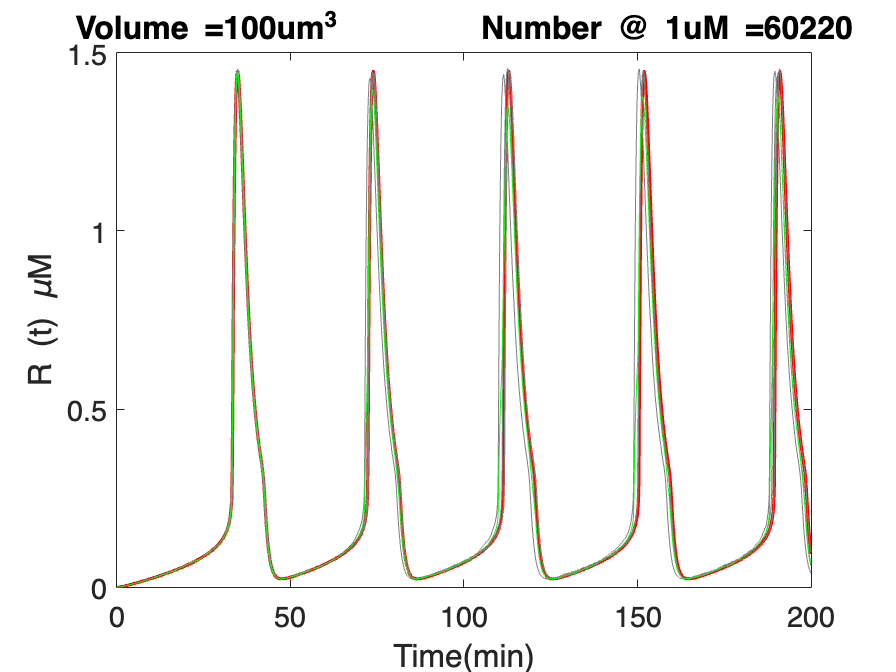

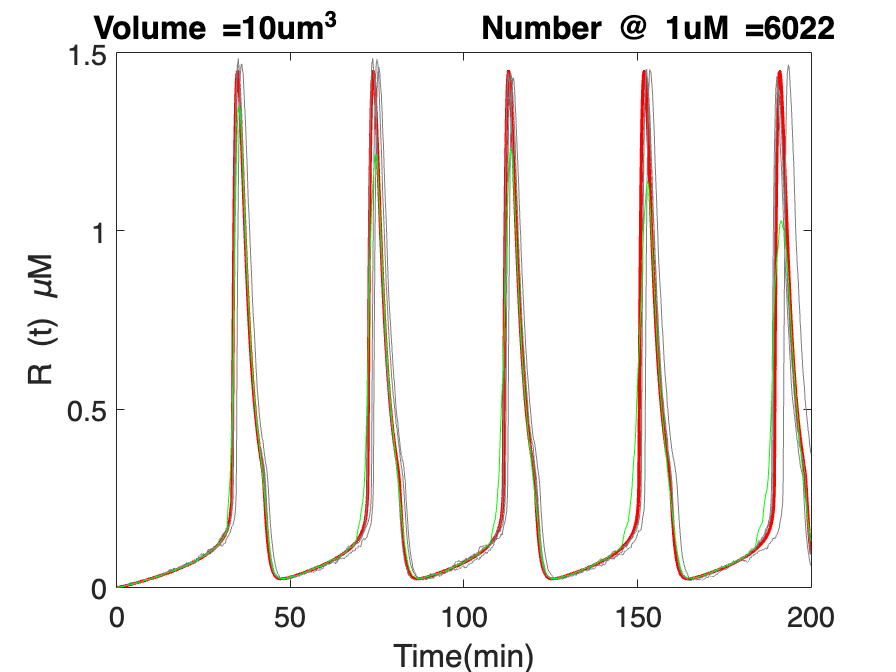

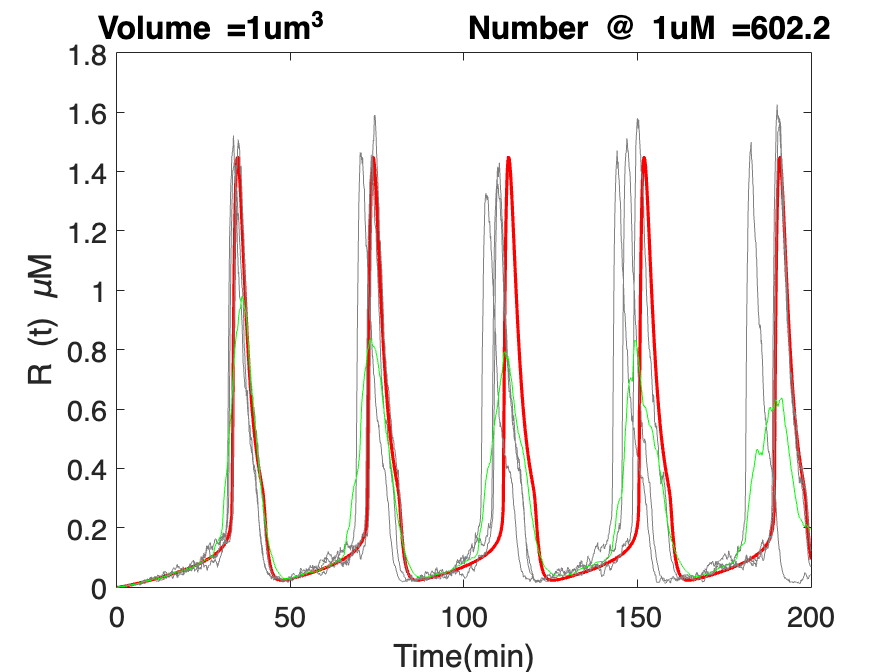

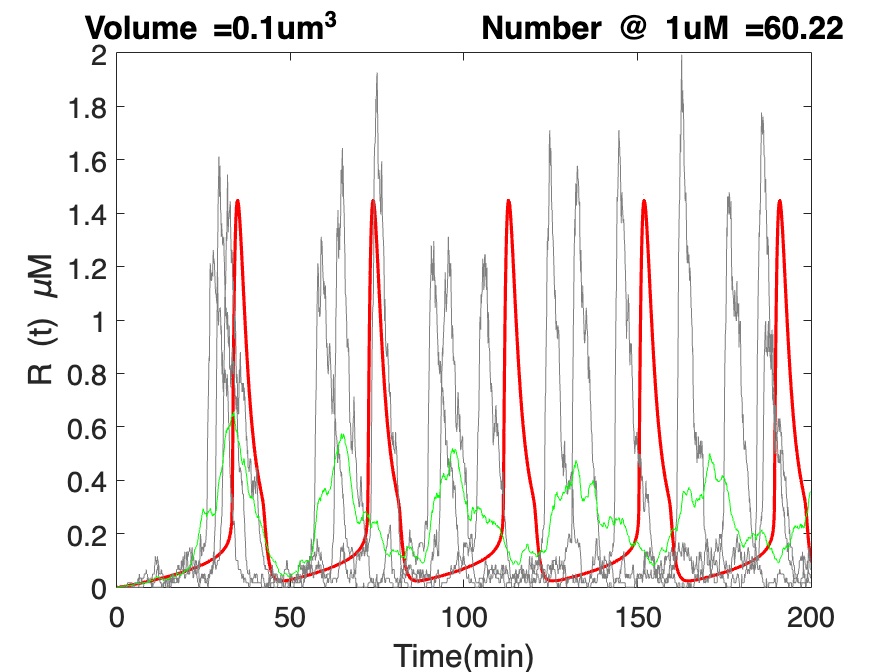

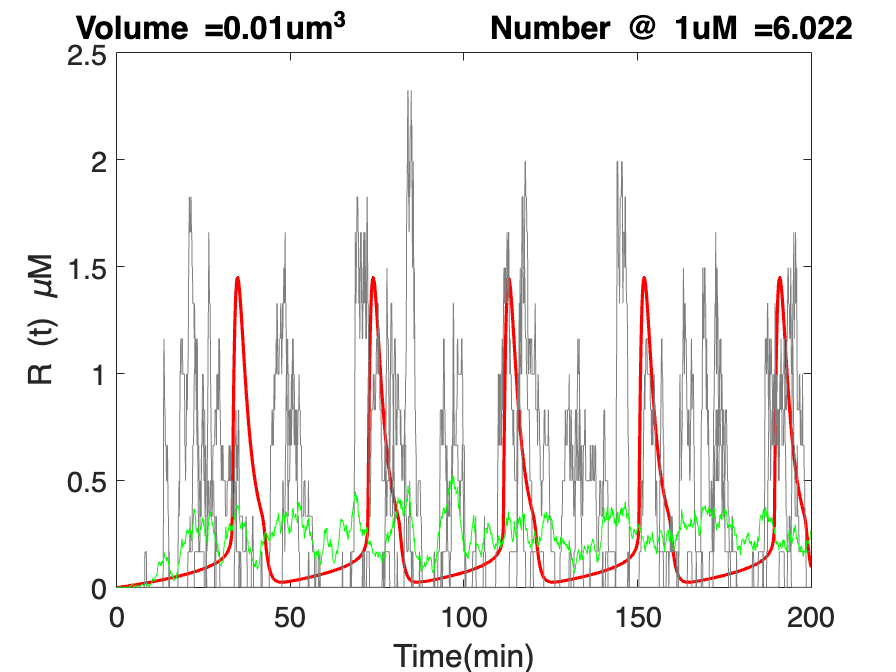

p.Na = 6.022d23;  			            %avogadro number (molecules per L)
p.Signal = 0.25;                        %Signal in the middle of the oscillating range

figure
vol=[100,10,1,0.1,0.01];                % volume in um^3

%%%% Now loop over all volumes
for v=1:length(vol)
p.volume = vol(v);				        %volume of cell in uM^(3) 
p.uM2num = 1d-6*1d-15*p.Na*p.volume;    % #molecules in a cell of volume p.volume in um^3

%%%%%%%%%%%%%%%% Now set up the Gillespie algorithm

%%%%%%%%%%%%%%%%%%% simulation parameters
p.startTime = 0;                    % start time of the simulation in seconds
p.endTime =  200;                   % end time
p.nrep = min(30,300/vol(v));        % number of replicate simulations 
p.dtForOutput=0.1;                  % time interval to store the data

%%%%%%%%%%% enter the propensities in the function calculatePropensities   
% a subtlety here is that you need to convert p.Signal from concentration to number by multiplying by p.uM2num
% another subtlety is that you must use k4*p.uM2num (and not just k4) in the GK funtion) 
calculatePropensities = @(X,p)[ ...
    p.k1 * p.Signal * p.uM2num; ...
    (p.k0p + p.k0*(GK(p.k3*X(2), p.k4*p.uM2num, p.J3, p.J4)))*X(1); ...
    p.k2 * X(2) ...
];

%%%%%%%%%%% Define the stochiometry matrix 
stochiometry = [ ...
    1, -1, 0; ...
    0, 1, -1 ...
];

 %%%%%%%%%% Now run the simulation
[X_gil,T_gil] = gillespie(X0, calculatePropensities, stochiometry, p);

%%%%%%% calculate the average value of X and R over the replicates into X_gilAv
% you'll have to look at exactly what is in X_gil
X_avg = mean(X_gil, 2);

%%%%%%%%%%%%% Now plot everything
figure
plot(t_mid, X_mid(:,2),'-r','linewidth',2)     %plot the ODE solution
hold on
for ii=1:3 %%% plot some of the trajectories (note division by p.uM2num to convert to uM  
    pp = plot(T_gil, X_gil(:, ii, 2)./p.uM2num, '-', 'linewidth', 0.25, 'Color', [0.5,0.5,0.5]);
    pp.Color(4) = 0.75;   %%%%% make it transparent
end

%plot the average value of R over the replicates (divide by p.uM2num to convert to uM)
plot(T_gil, X_avg(:, 2)./p.uM2num, 'g-');
title(strcat('Volume =',num2str(p.volume),'um^3','         Number @ 1uM =',num2str(p.uM2num)));
box on
xlabel('Time(min)')
ylabel('R (t) \muM')
set(gca,'FontName','Helvetica','FontSize',18,'GridAlpha',0.15,'color','w','LineWidth',1);
drawnow;
end

*(iv) (3 points) How do the oscillations change qualitatively as the number of molecules changes (amplitude compared to the ODE, amplitude in each cycle, accuracy of the frequency, variation from replicate to replicate)? Is there a minimum number of molecules to get oscillations? No more than 300 words in the *`mlx`* file. Hand in the *`pdf`*. *

At higher volumes, the stochastic simulations more closely resemble and replicate the trajctories drawn from ODE solutions. The variation between individual replicates increases significantly as the volume (and thus the number of molecules) decreases. Both amplitude and frequency deviate from the ODE-predicted values. The average oscillation amplitudes tend to be lower than the ODE-predicted ones as the volume decreases, while the average frequency tends to be higher. This is consistent with what we usually expect; greater the number of entities sampled and used to reproduce a measure, the more statistically close to the real (or expected) value it is, and of more relevance here, it produces a more confident and less varying (less noisy) estimate. 

Hence, there is certainly a minimum number of molecules required to get reliable estimates of species concentrations and the system's oscillations in general from the stochatic simulations; in this case, volumes of 10 micro-meter-cubed and above seem to produce good estimates (i.e., plots 1 and 2).

*(v) BONUS (5 points) For graduate students, bonus for undergraduates. What happens when you are near the critical signal (i.e., in the oscillation region of signals but near the critical value). Explore using simulations and describe your findings.*

*** try Signal = 0.145 and 0.35: the synchronization is less good and it desynchronizes faster ***

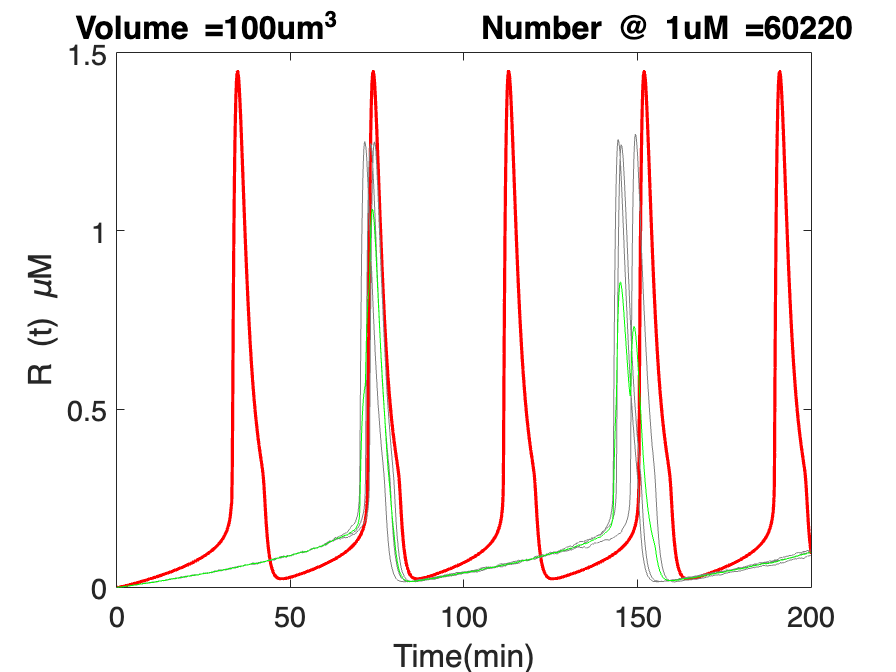

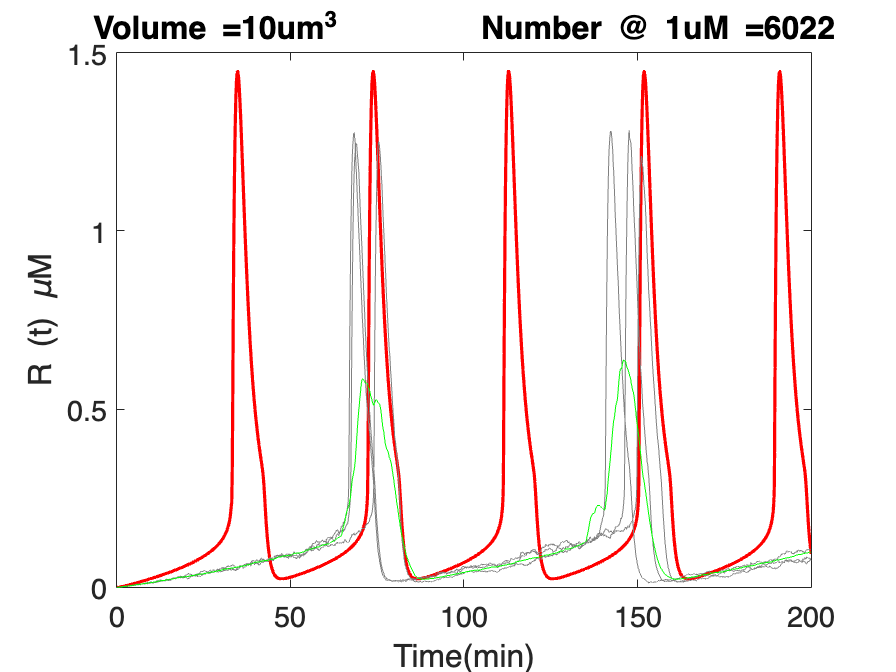

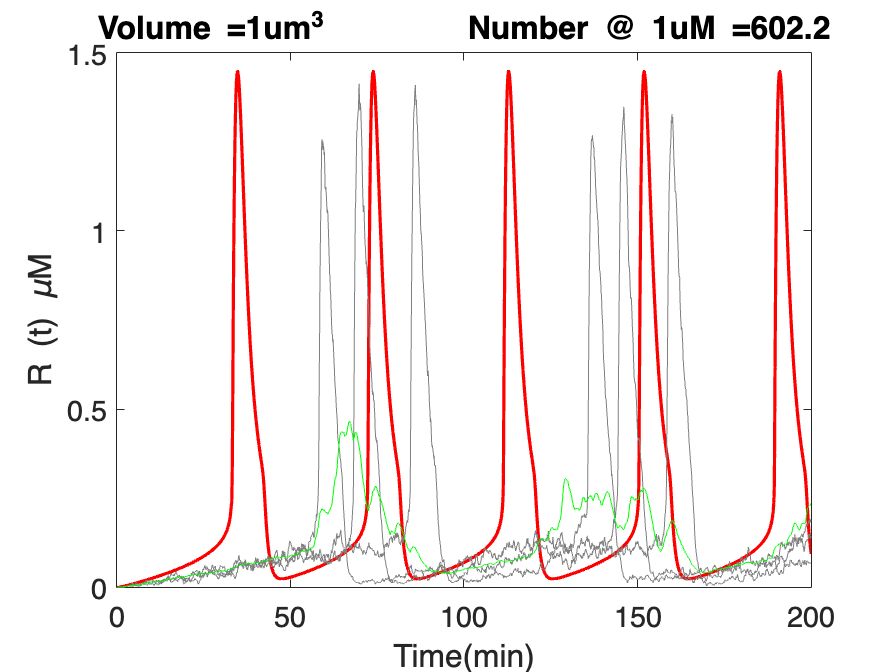

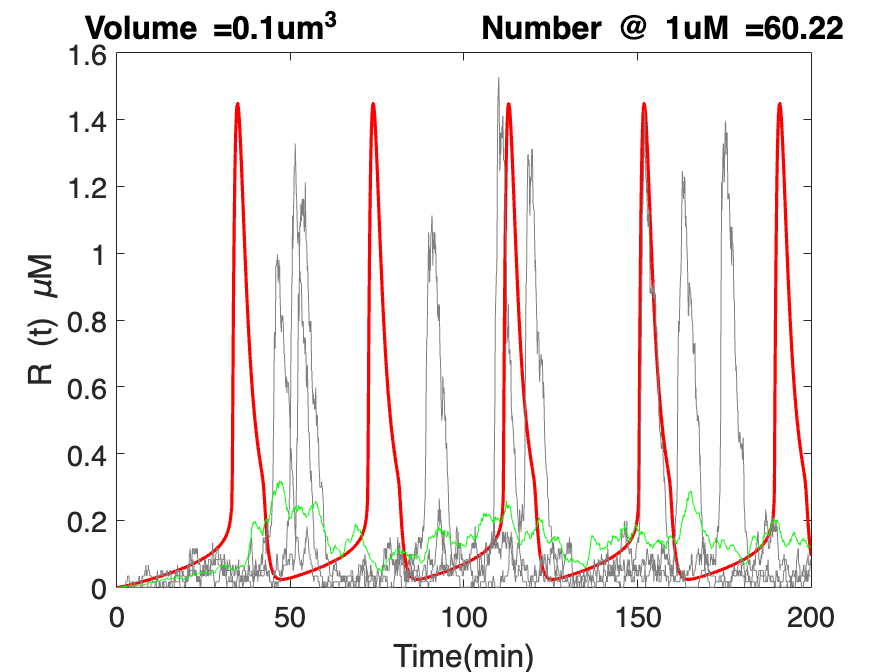

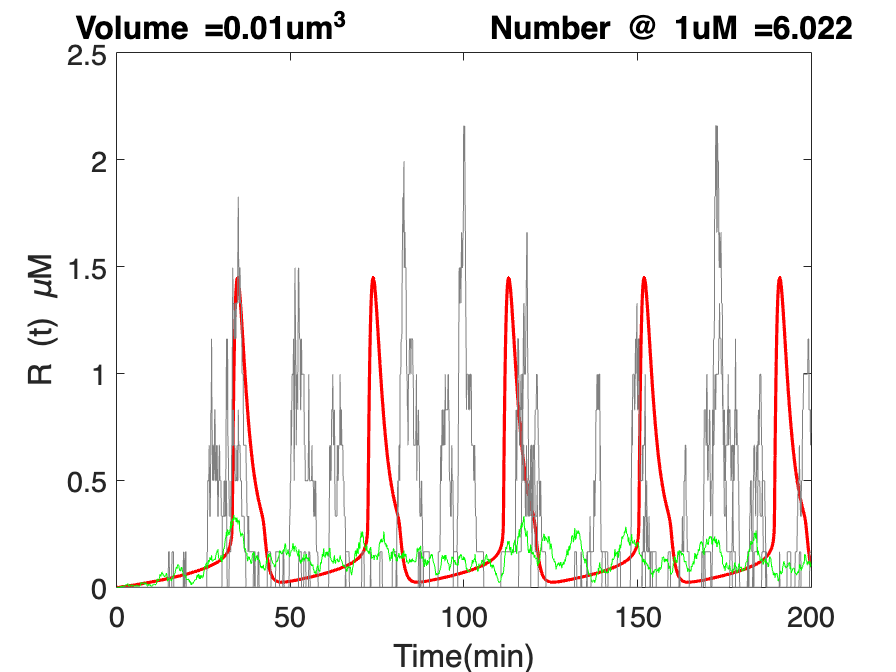

p.Na = 6.022d23;  			            %avogadro number (molecules per L)
p.Signal = 0.145;                        %Signal in the middle of the oscillating range

figure
vol=[100,10,1,0.1,0.01];                % volume in um^3

%%%% Now loop over all volumes
for v=1:length(vol)
p.volume = vol(v);				        %volume of cell in uM^(3) 
p.uM2num = 1d-6*1d-15*p.Na*p.volume;    % #molecules in a cell of volume p.volume in um^3

%%%%%%%%%%%%%%%% Now set up the Gillespie algorithm

%%%%%%%%%%%%%%%%%%% simulation parameters
p.startTime = 0;                    % start time of the simulation in seconds
p.endTime =  200;                   % end time
p.nrep = min(30,300/vol(v));        % number of replicate simulations 
p.dtForOutput=0.1;                  % time interval to store the data

%%%%%%%%%%% enter the propensities in the function calculatePropensities   
% a subtlety here is that you need to convert p.Signal from concentration to number by multiplying by p.uM2num
% another subtlety is that you must use k4*p.uM2num (and not just k4) in the GK funtion) 
calculatePropensities = @(X,p)[ ...
    p.k1 * p.Signal * p.uM2num; ...
    (p.k0p + p.k0*(GK(p.k3*X(2), p.k4*p.uM2num, p.J3, p.J4)))*X(1); ...
    p.k2 * X(2) ...
];

%%%%%%%%%%% Define the stochiometry matrix 
stochiometry = [ ...
    1, -1, 0; ...
    0, 1, -1 ...
];

 %%%%%%%%%% Now run the simulation
[X_gil,T_gil] = gillespie(X0, calculatePropensities, stochiometry, p);

%%%%%%% calculate the average value of X and R over the replicates into X_gilAv
% you'll have to look at exactly what is in X_gil
X_avg = mean(X_gil, 2);

%%%%%%%%%%%%% Now plot everything
figure
plot(t_mid, X_mid(:,2),'-r','linewidth',2)     %plot the ODE solution
hold on
for ii=1:3 %%% plot some of the trajectories (note division by p.uM2num to convert to uM  
    pp = plot(T_gil, X_gil(:, ii, 2)./p.uM2num, '-', 'linewidth', 0.25, 'Color', [0.5,0.5,0.5]);
    pp.Color(4) = 0.75;   %%%%% make it transparent
end

%plot the average value of R over the replicates (divide by p.uM2num to convert to uM)
plot(T_gil, X_avg(:, 2)./p.uM2num, 'g-');
title(strcat('Volume =',num2str(p.volume),'um^3','         Number @ 1uM =',num2str(p.uM2num)));
box on
xlabel('Time(min)')
ylabel('R (t) \muM')
set(gca,'FontName','Helvetica','FontSize',18,'GridAlpha',0.15,'color','w','LineWidth',1);
drawnow;
end

time = 90.55 Used all random numbers. Generating new batch
time = 166.21 Used all random numbers. Generating new batch
time = 89.68 Used all random numbers. Generating new batch
time = 166.16 Used all random numbers. Generating new batch
time = 91.78 Used all random numbers. Generating new batch
time = 164.73 Used all random numbers. Generating new batch


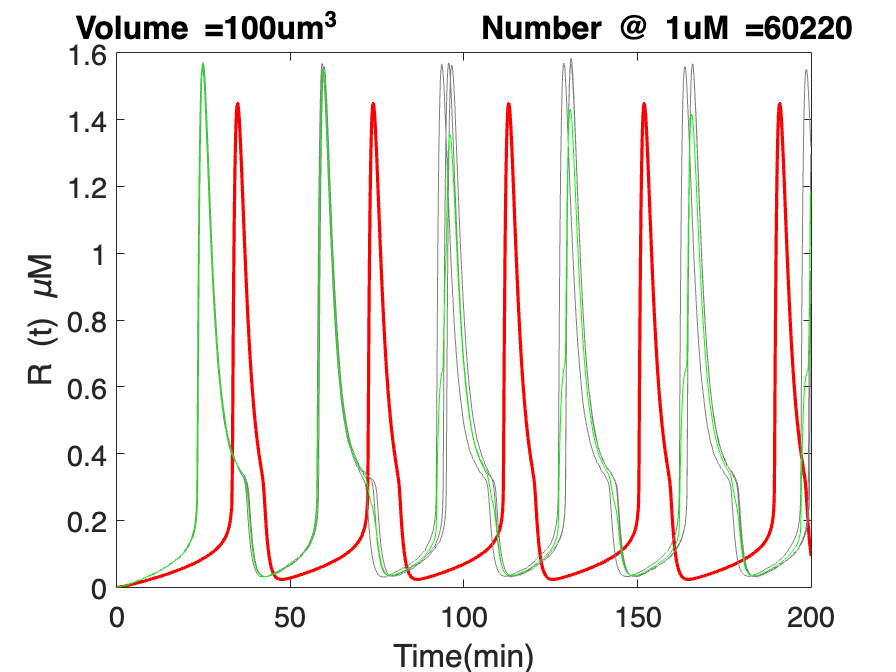

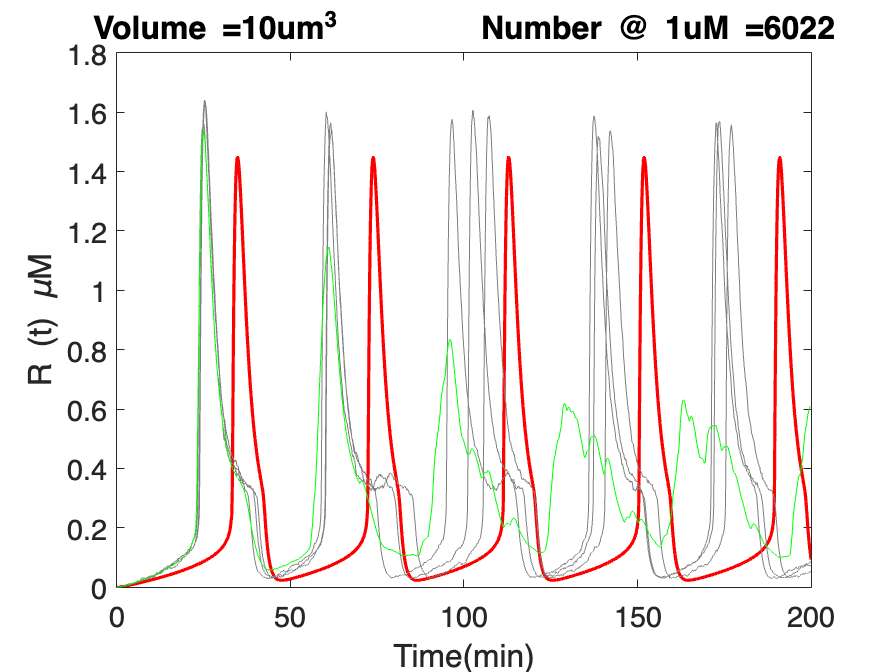

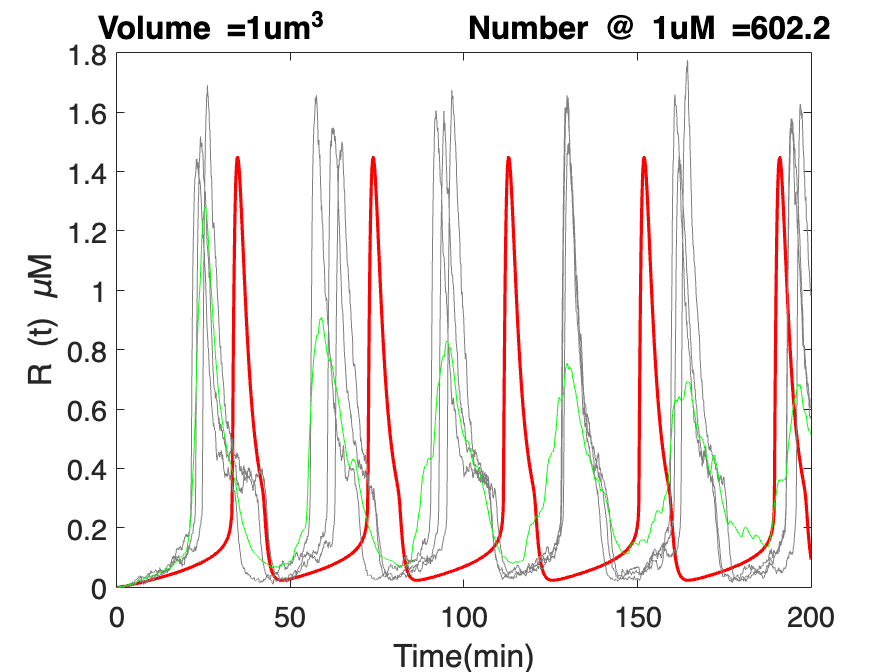

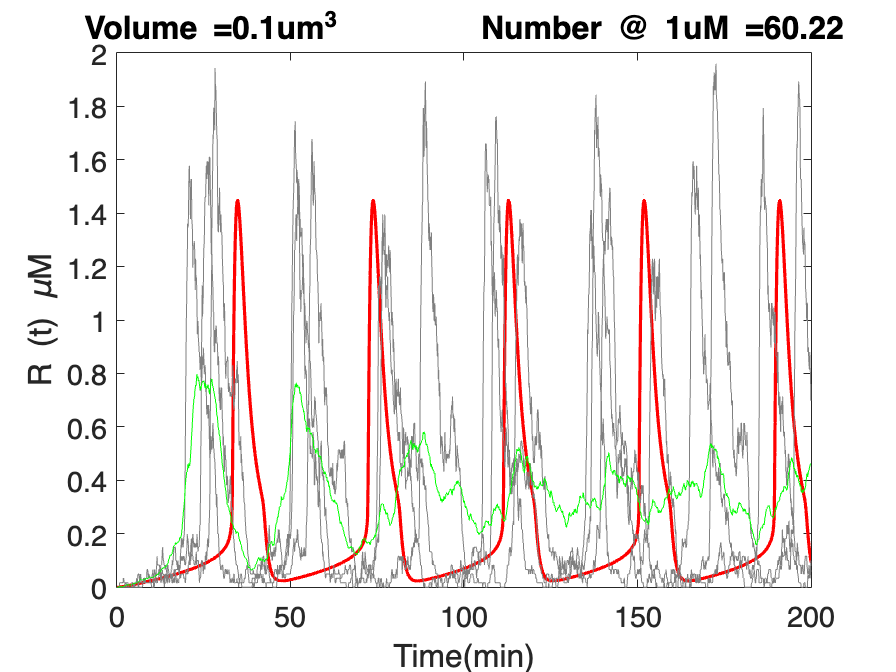

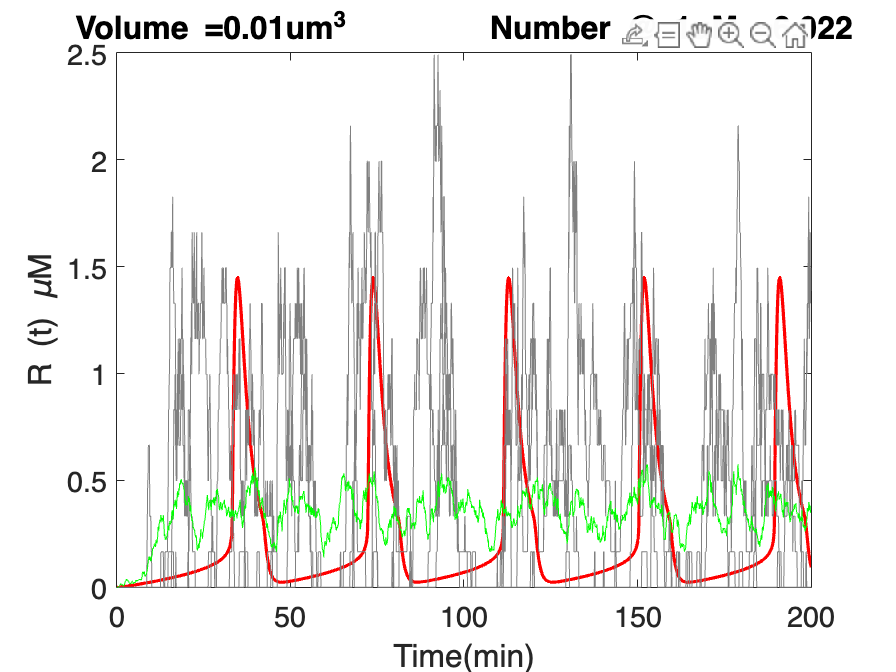

p.Na = 6.022d23;  			            %avogadro number (molecules per L)
p.Signal = 0.35;                        %Signal in the middle of the oscillating range

figure
vol=[100,10,1,0.1,0.01];                % volume in um^3

%%%% Now loop over all volumes
for v=1:length(vol)
p.volume = vol(v);				        %volume of cell in uM^(3) 
p.uM2num = 1d-6*1d-15*p.Na*p.volume;    % #molecules in a cell of volume p.volume in um^3

%%%%%%%%%%%%%%%% Now set up the Gillespie algorithm

%%%%%%%%%%%%%%%%%%% simulation parameters
p.startTime = 0;                    % start time of the simulation in seconds
p.endTime =  200;                   % end time
p.nrep = min(30,300/vol(v));        % number of replicate simulations 
p.dtForOutput=0.1;                  % time interval to store the data

%%%%%%%%%%% enter the propensities in the function calculatePropensities   
% a subtlety here is that you need to convert p.Signal from concentration to number by multiplying by p.uM2num
% another subtlety is that you must use k4*p.uM2num (and not just k4) in the GK funtion) 
calculatePropensities = @(X,p)[ ...
    p.k1 * p.Signal * p.uM2num; ...
    (p.k0p + p.k0*(GK(p.k3*X(2), p.k4*p.uM2num, p.J3, p.J4)))*X(1); ...
    p.k2 * X(2) ...
];

%%%%%%%%%%% Define the stochiometry matrix 
stochiometry = [ ...
    1, -1, 0; ...
    0, 1, -1 ...
];

 %%%%%%%%%% Now run the simulation
[X_gil,T_gil] = gillespie(X0, calculatePropensities, stochiometry, p);

%%%%%%% calculate the average value of X and R over the replicates into X_gilAv
% you'll have to look at exactly what is in X_gil
X_avg = mean(X_gil, 2);

%%%%%%%%%%%%% Now plot everything
figure
plot(t_mid, X_mid(:,2),'-r','linewidth',2)     %plot the ODE solution
hold on
for ii=1:3 %%% plot some of the trajectories (note division by p.uM2num to convert to uM  
    pp = plot(T_gil, X_gil(:, ii, 2)./p.uM2num, '-', 'linewidth', 0.25, 'Color', [0.5,0.5,0.5]);
    pp.Color(4) = 0.75;   %%%%% make it transparent
end

%plot the average value of R over the replicates (divide by p.uM2num to convert to uM)
plot(T_gil, X_avg(:, 2)./p.uM2num, 'g-');
title(strcat('Volume =',num2str(p.volume),'um^3','         Number @ 1uM =',num2str(p.uM2num)));
box on
xlabel('Time(min)')
ylabel('R (t) \muM')
set(gca,'FontName','Helvetica','FontSize',18,'GridAlpha',0.15,'color','w','LineWidth',1);
drawnow;
end

Close to the the critical values, the system is at the periphery between a stable periodic solution (the oscilation around the unstable fixed point) and the tendency to settle at a stable fixed point. Hence, although there is some periodicity in the system (most evident in the highest volume plots in each case - also the most reliabe, since it produces the best estimate for a given parameter set), it is neither very close to the expected ODE-predicted trajectory, nor does it hold its periodicity for long (i.e, desynchronizes). Over more time steps, it might even reach a stable steady state. Hence, either the amplitude, frequency, or both, do not resemble the expected periodic trajectories in these critical cases.